# TEST71 

Copyright 2020 Richard J. Cui. Created: Sat 02/29/2020 10:24:49.894 PM

Revision: 0,1 $  $Date: Sat 02/29/2020 10:24:49.894 PM $

1026 Rocky Creek Dr NE

Rochester, MN 55906, USA

Email: richard.cui@utoronto.ca

## Import the data into MATLAB

fname = 'test71.bin'; % binary data file name
sig_len = 18; % signal length in samples
num_ch = 15; % number of channels
num_trl = 137; % number of trials
fs = 200; % sampling frequency (Hz)

dat = readdat(fname, sig_len, num_ch, num_trl);

## Preprocess the data

dat_pre = dat;

### Preprocessing step 1 (cf. Ding et al, Biol. Cybern. 2000)

dat_pre = pre_subt_divs(dat_pre); % subtract temporal mean and divided by STD

### Preprocessing step 2 and 3 (cf. Ding et al, Biol. Cybern. 2000)

dat_pre = pre_sube_divs(dat_pre); % subtract ensemble mean and divided by STD

## AIC test

win_len = 10; % window length
max_order = 8; % maxium model order
AIC = aic_test(dat_pre, win_len, max_order);

Plot the result

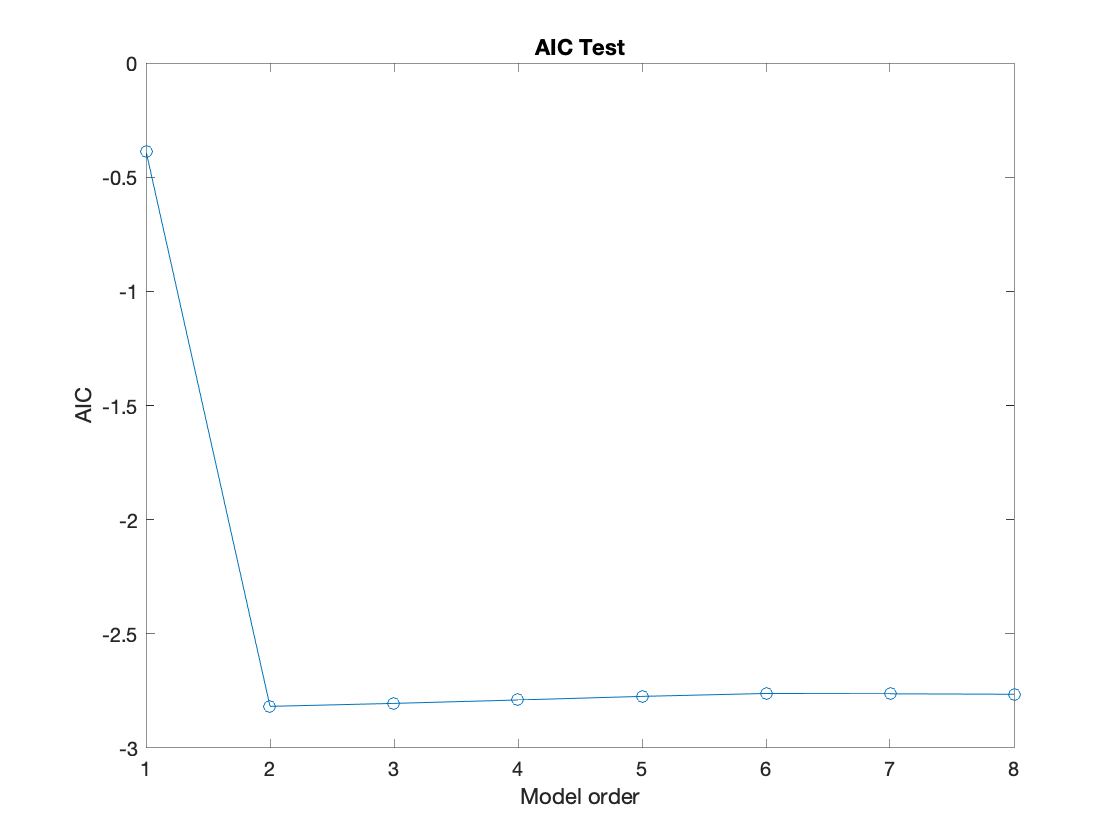

figure
plot(AIC', '-o')
xlabel('Model order')
ylabel('AIC')
title('AIC Test')

## Build moving window multivariate AR model

model_ord = 4; % model order
startp = 1; % start position in samples
endp = 15; % end position

Find the window center

num_win = endp-win_len+1;
win_c = (1/2+(0:(num_win-1)))*win_len/fs*1000; % window centers in ms

Calculate the model

[A, Ve] = mov_mul_model(dat_pre, model_ord, startp, endp, win_len);

## Model tests

### Consistency test

ratio = consistencytest(dat_pre, A, Ve);

Plot the result

figure
plot(win_c, ratio, '-o')
ylim([0, 100])
title('Consistency Test')
xlabel('Window center (ms)')
ylabel('Consistency (%)')

### Whiteness test

resid = whitenesstest(dat_pre, win_len, model_ord, startp, endp);

plot the result

figure
plot(win_c, resid, '-o')
ylim([0, 10])
hold on
plot(xlim, [5, 5], '--')
title('Whitness Test')
xlabel('Window center (ms)')
ylabel('Residue whiteness (%)')

### Stability test

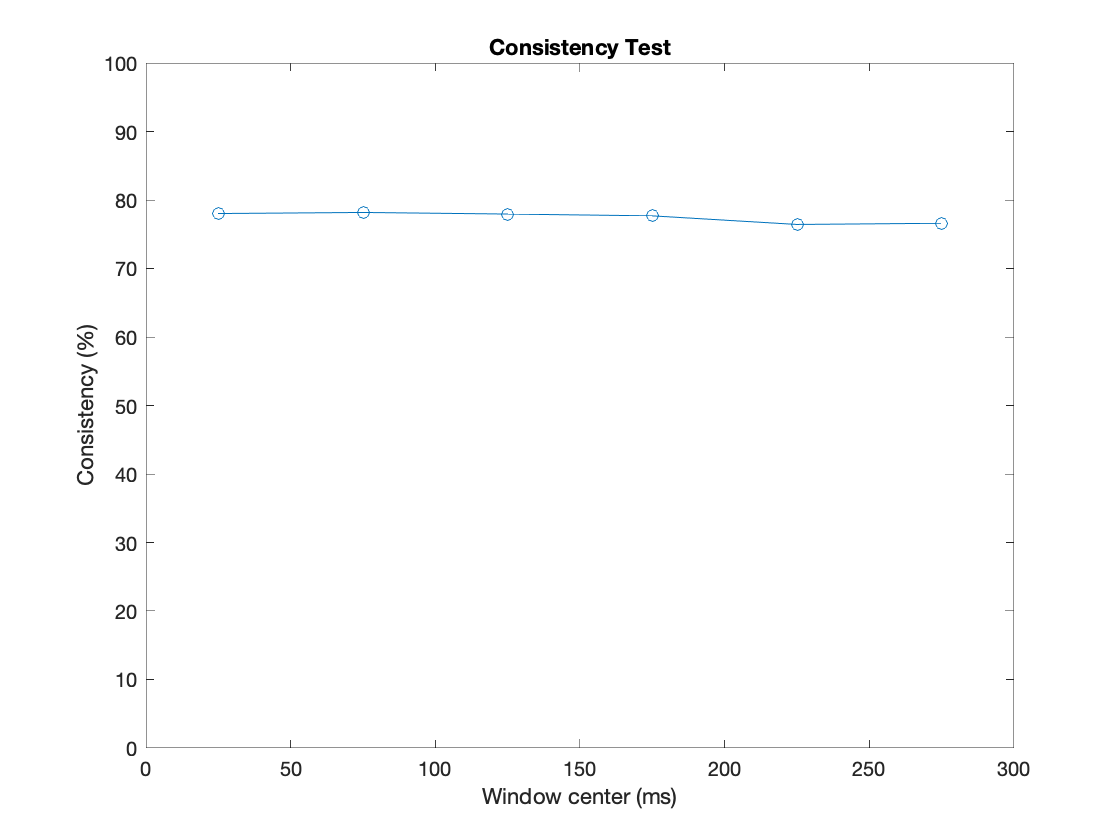

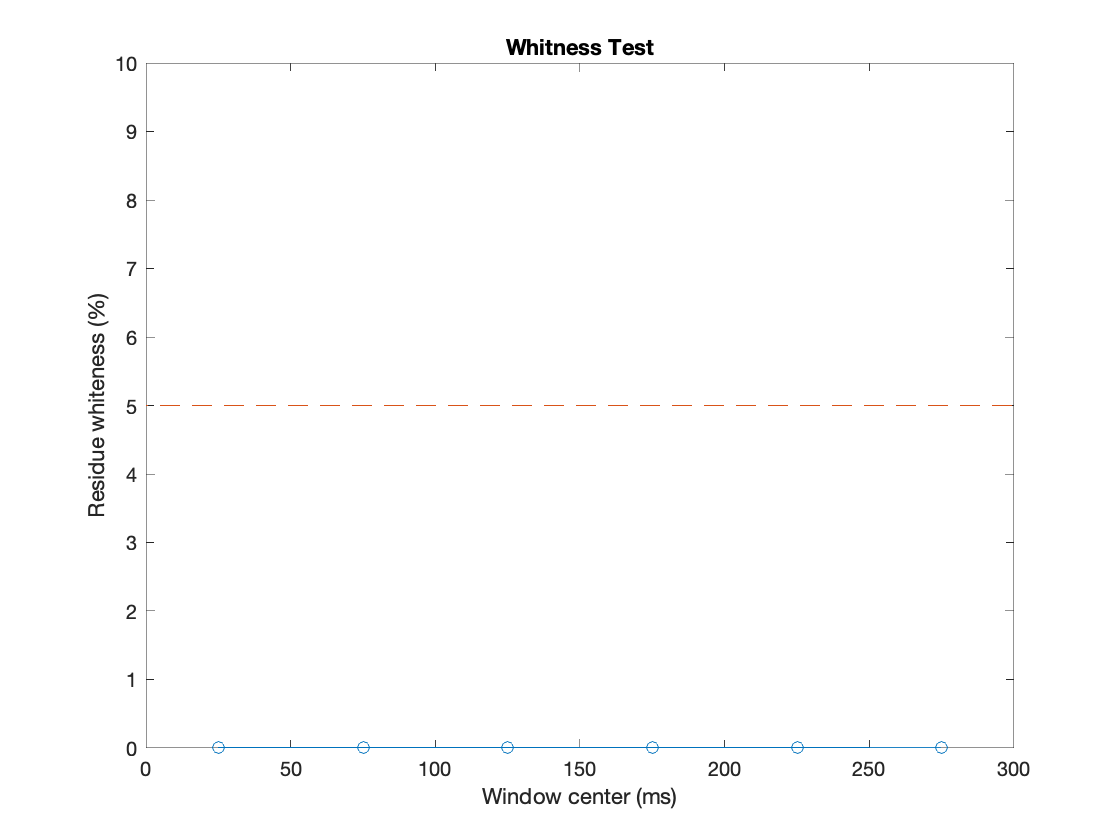

T = 1000; % number of samples to genenrate
le = lyap_batch(A, Ve, T);

Plot the result

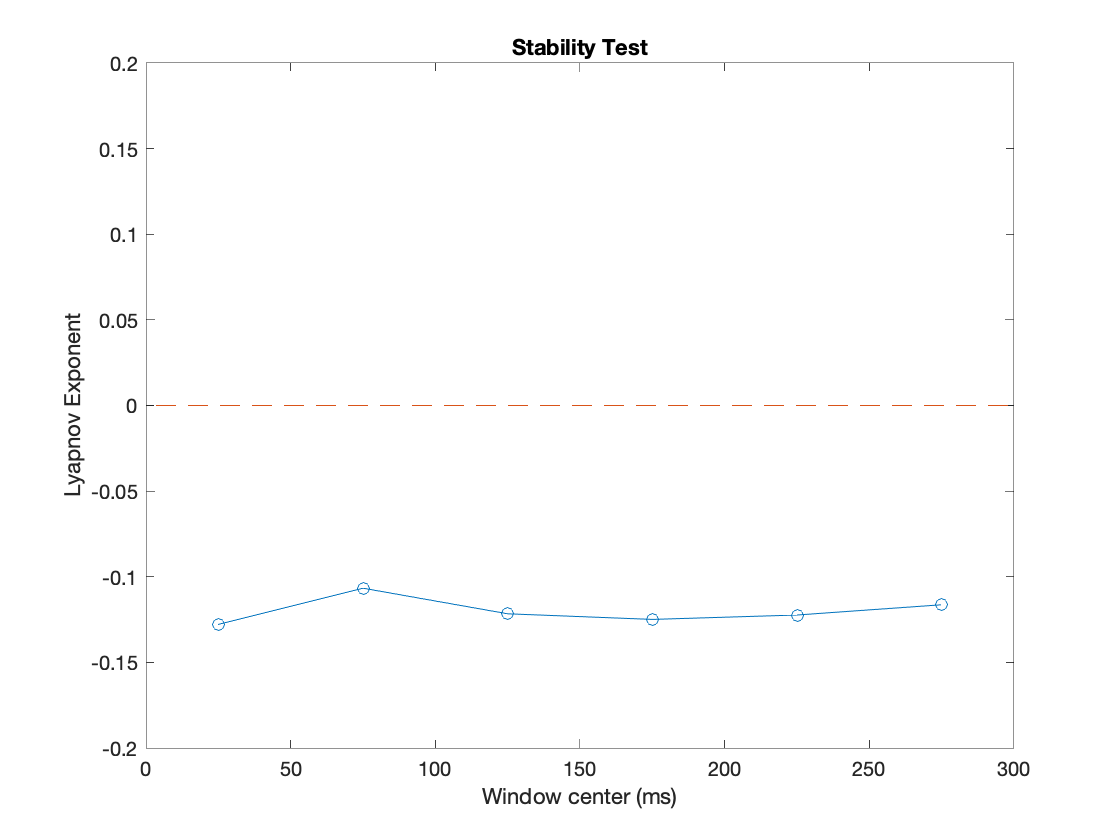

figure
plot(win_c, le, '-o')
hold on
plot(xlim, [0 0], '--')
title('Stability Test')
ylim([-.2 .2])
xlabel('Window center (ms)')
ylabel('Lyapnov Exponent')

## Auto power

nfb = 100; % number of frequency bins
power = autopower(A, Ve, nfb, fs);

### Plot the power of a specified channel

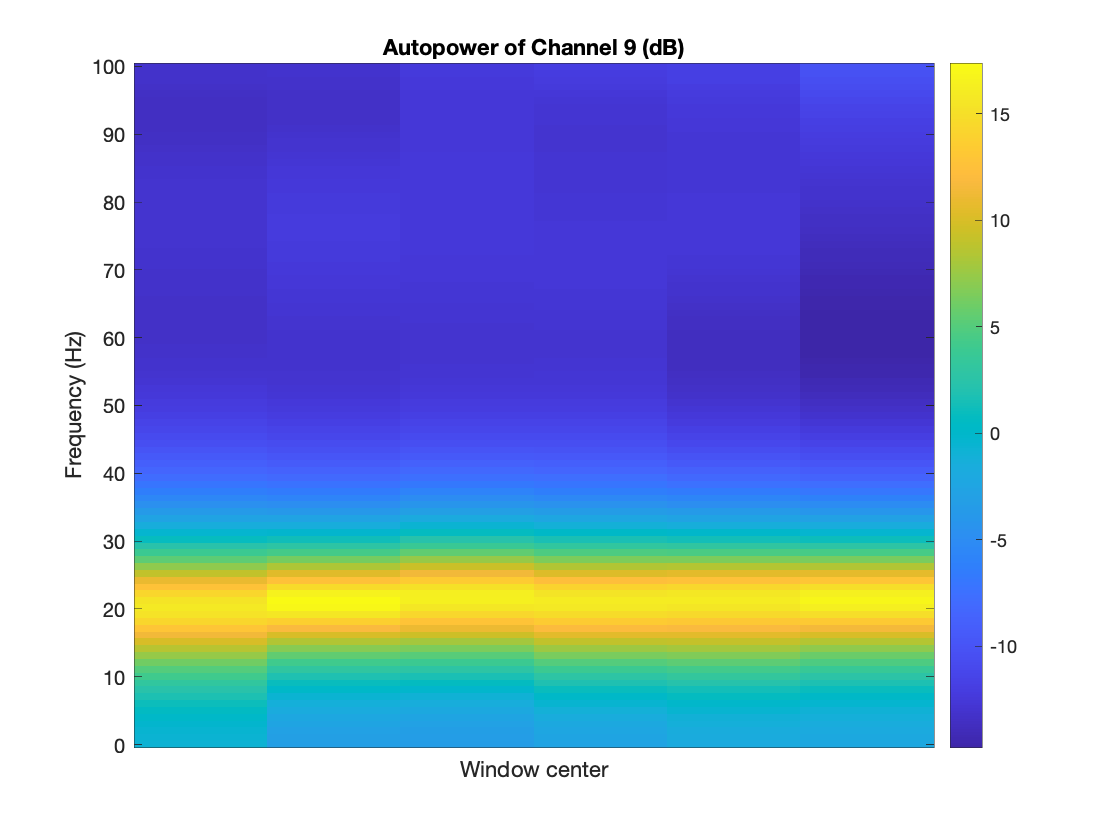

chx = 9;
po_view(power, fs, chx)
ax = gca;
ax.XTick = win_c;
ax.XLabel.String = 'Window center';

Plot the power of a specified channel at a specified window

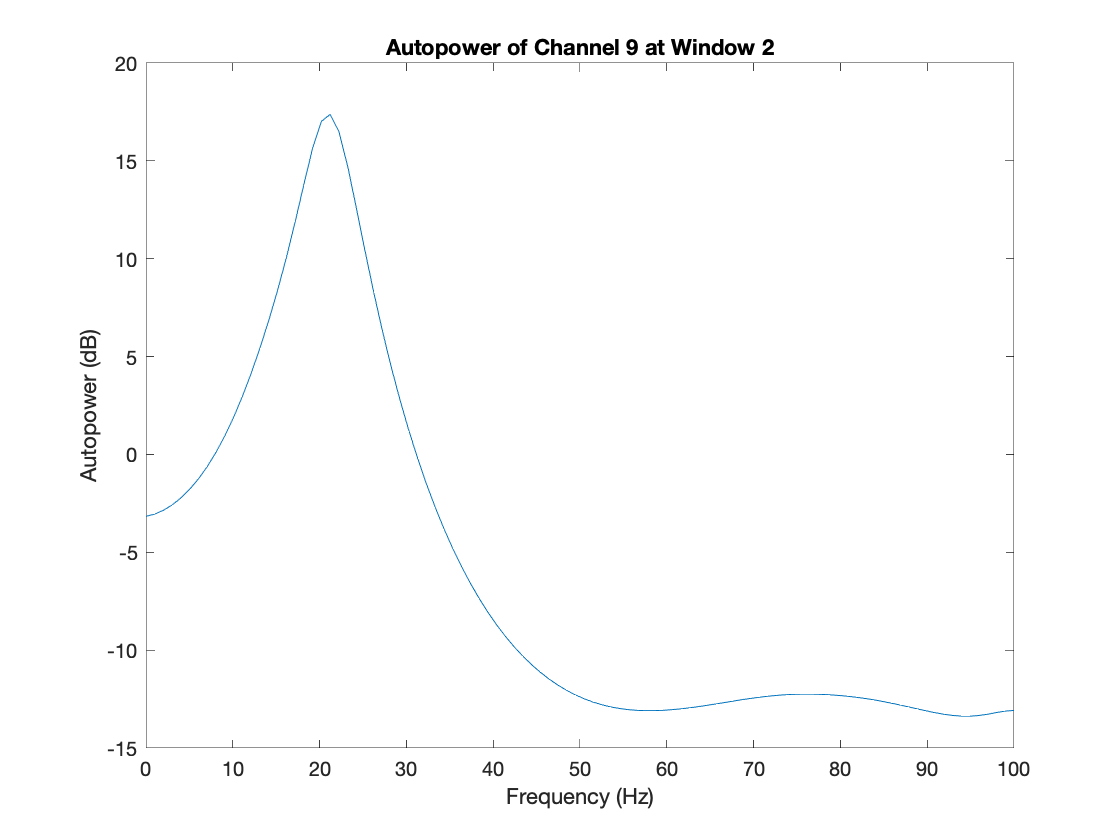

winidx = 2; % check window indexed at winidx
po_view(power, fs, chx, winidx)

## Pair coherence

coh = paircoherence(A, Ve, nfb, fs); % coherence

### Plot coherence for a specified channel pair

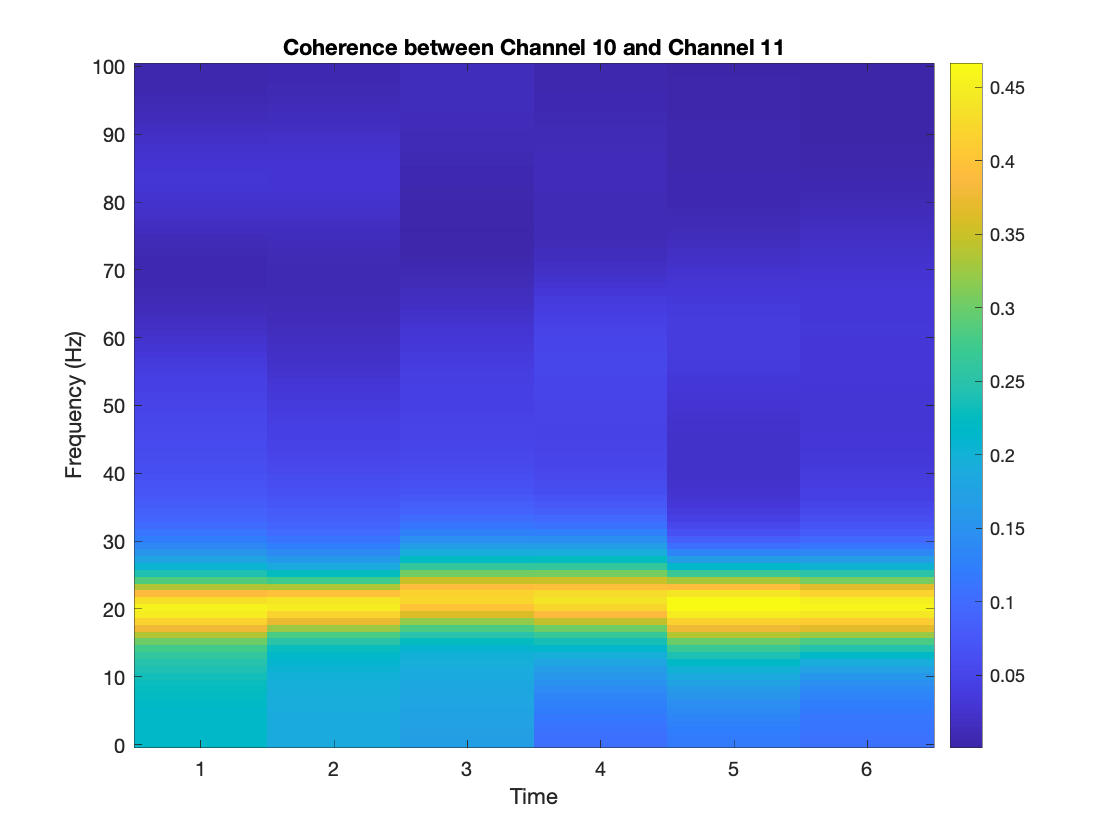

chx = 10;
chy = 11;
co_view(coh, chx, chy, fs)

### Plot coherence for a specified channel pair at a specified window

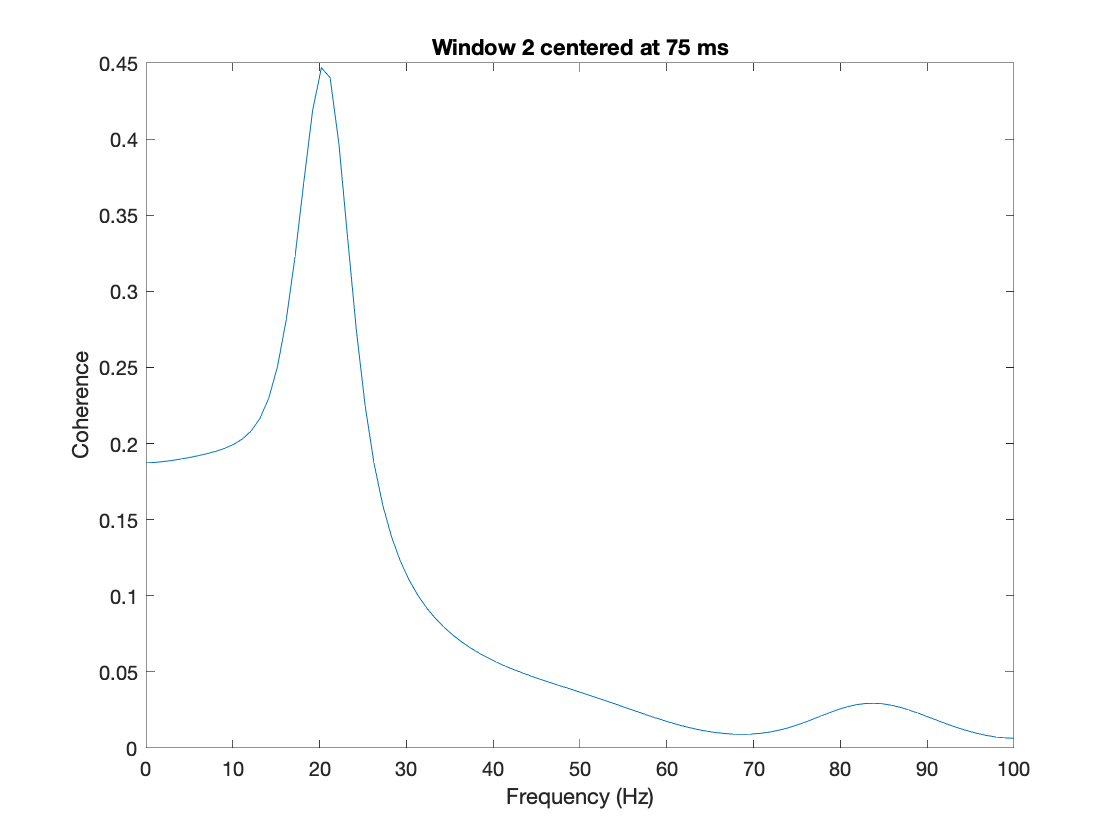

timen = [winidx, win_c(winidx)];
co_view(coh, chx, chy, fs, timen)

### Show coherence network

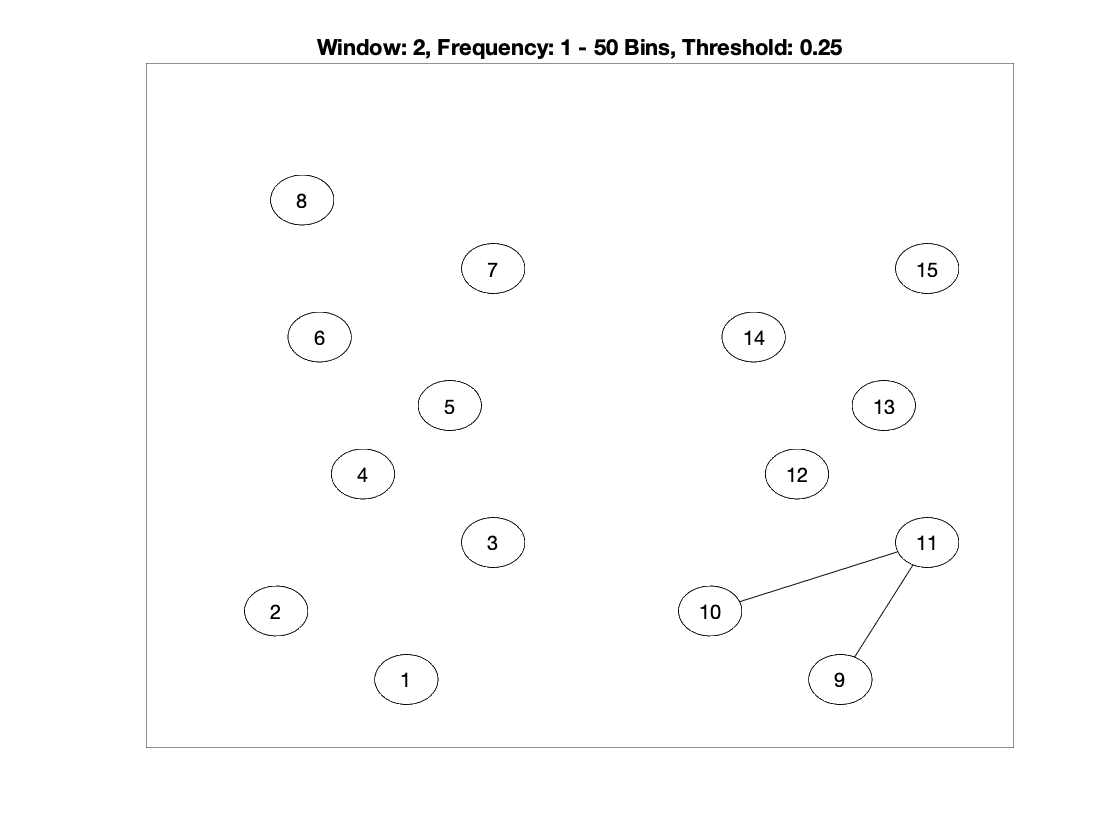

load location.mat
thre_coh = .25; % threshold
fre1 = 1; % start frequency bin
fre2 = 50; % end frequency bin
ch_intrest = 1:num_ch;
conetwork(coh, location, thre_coh, winidx, fre1, fre2, ch_intrest)

## Granger causality

fre_int = 0:fs/2; % frequencies of interest
[Fxy, Fyx] = mov_bi_ga(dat_pre, startp, endp, win_len, model_ord, fs, fre_int);

### Plot GC between specified channel pair

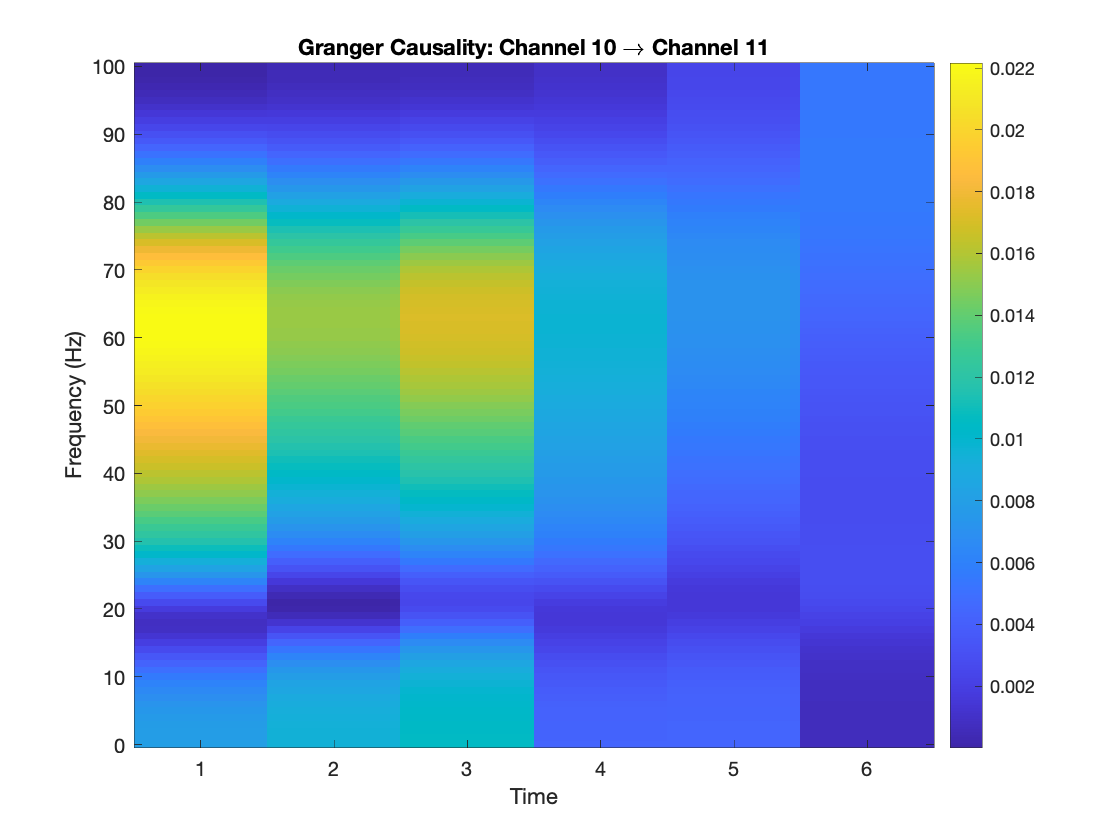

ga_view(Fxy, Fyx, fs, chx, chy)

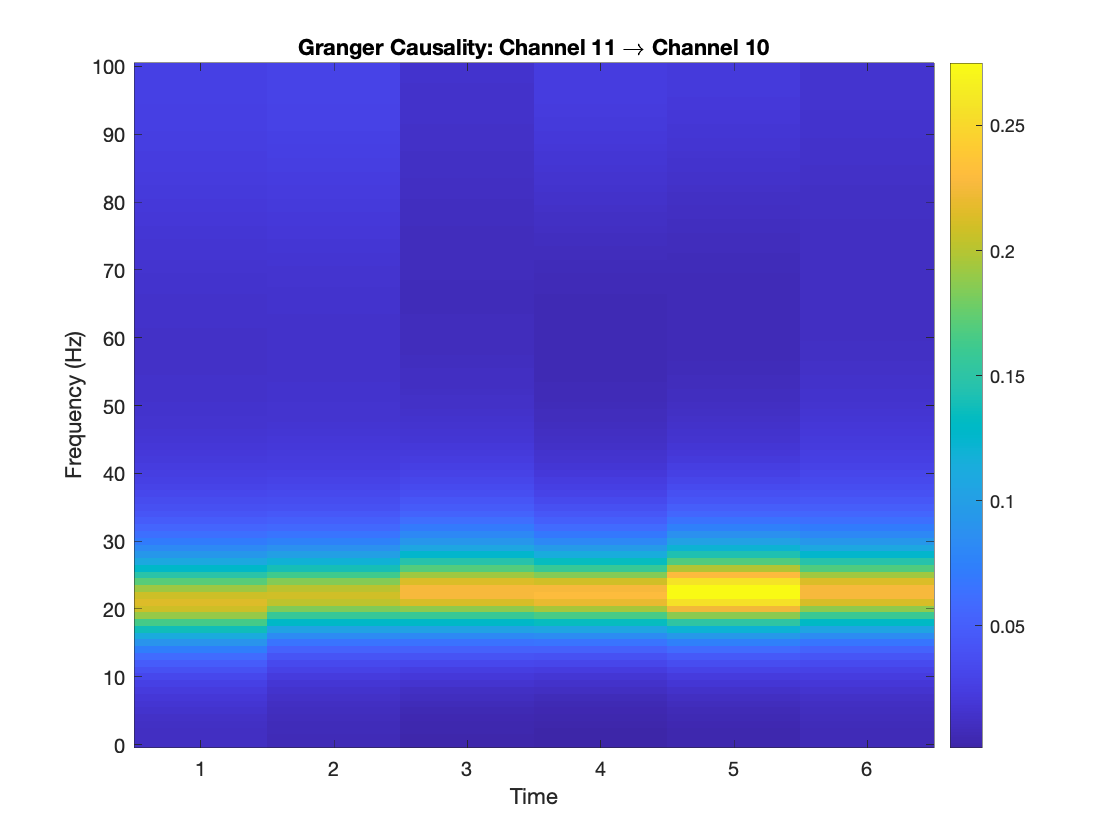

ga_view(Fxy, Fyx, fs, chy, chx)

### Plot GC between specified channel pair at a specified window

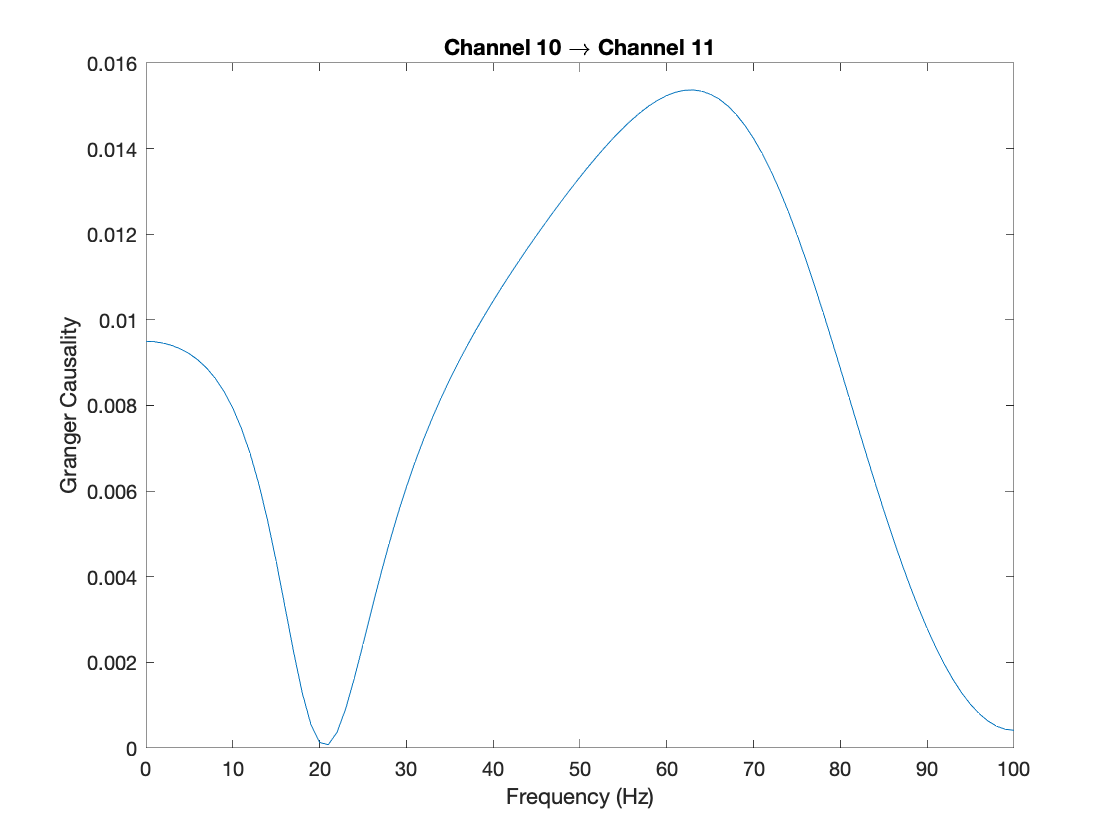

ga_view(Fxy, Fyx, fs, chx, chy, winidx)

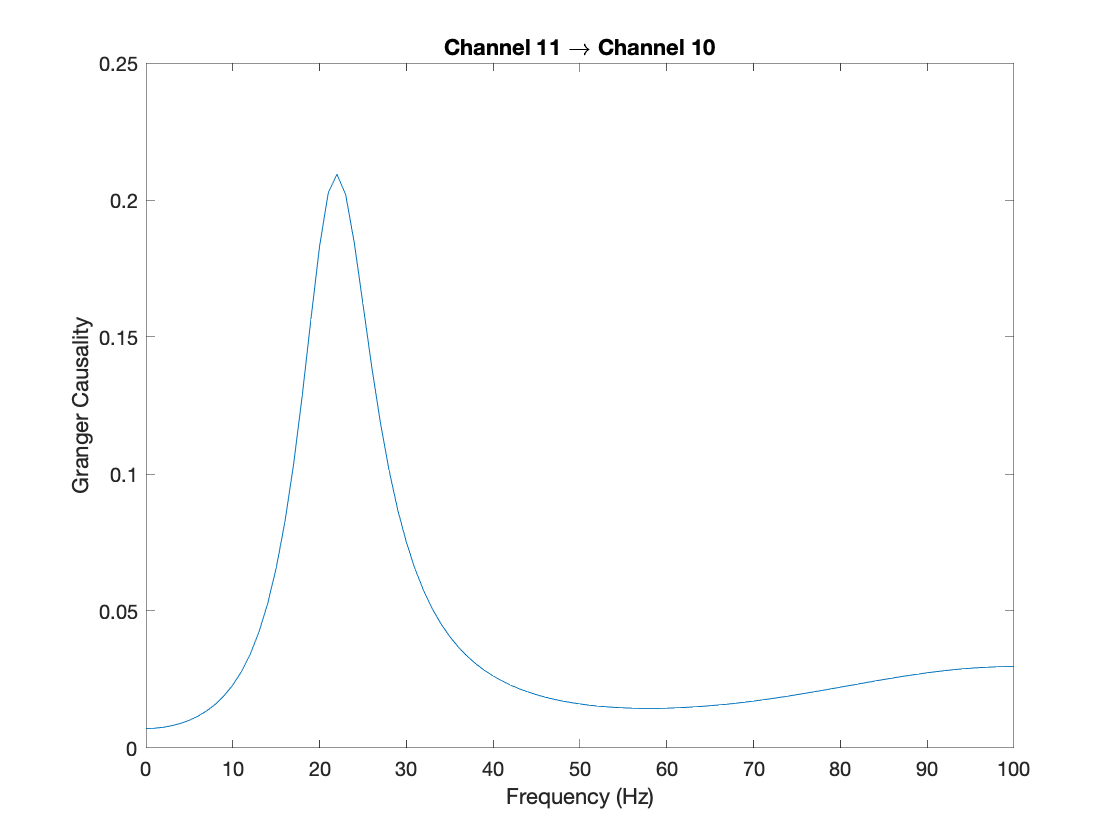

ga_view(Fxy, Fyx, fs, chy, chx, winidx)

### Plot GC network

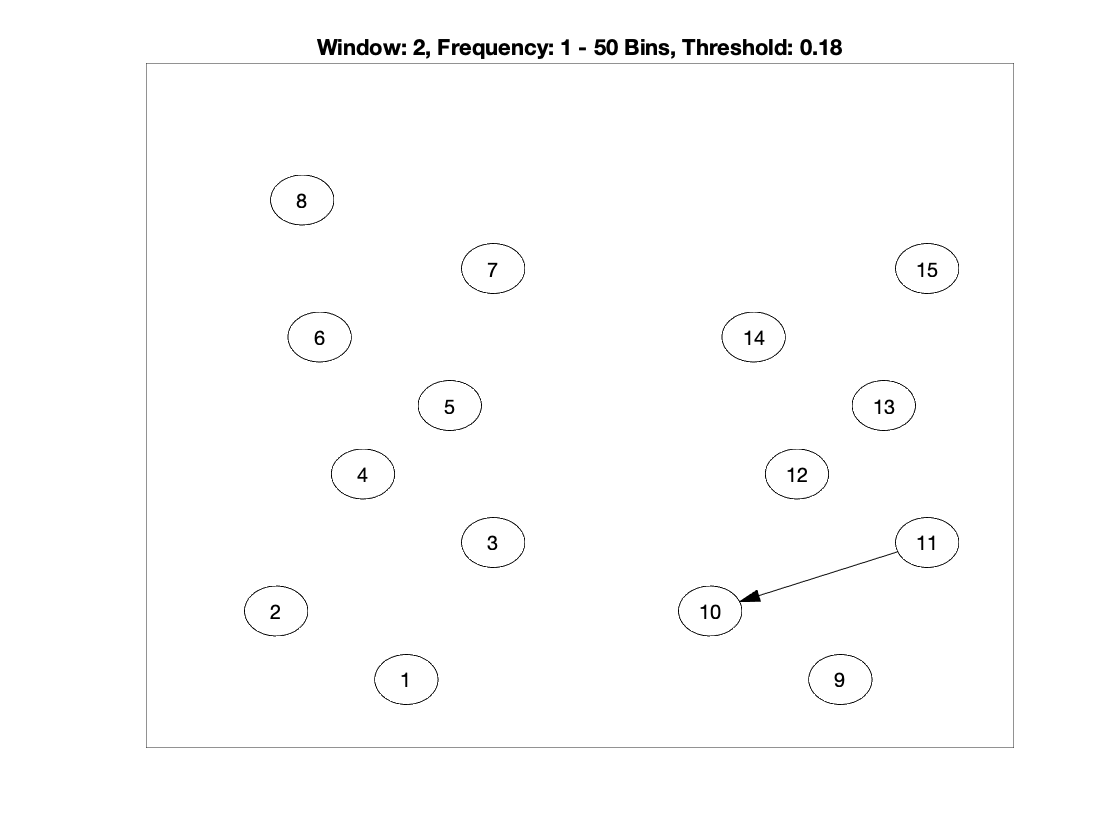

thre_gc = .18; % threshold of GC
ganetwork(Fxy, Fyx, location, thre_gc, winidx, fre1, fre2, ch_intrest)